img = imread("project\images\color-palette-1.jpg");
img = im2double(img);


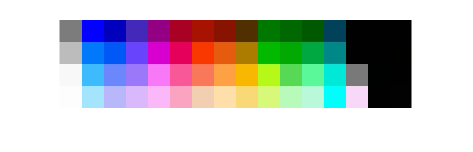

palette = zeros(64,3);
count = 1;

for i = 1:32:128
    for j = 1:32:512
        im = img(i:i+31,j:j+31,:);
        color =  mean(mean(im(:,:,:)));
        palette(count,:) = color;
        count = count + 1;
    end
end
imshow(img);

t = Tiff('project\images\image-example-1.tif','r');
% t = Tiff('project\images\MVP_2.tif','r');
img = read(t);
img = imread("project\images\bird-1.jpg"); 
img = im2double(img);

% Get colors from image
[X,cmap] = rgb2ind(img, 20)

X = 1416×2124 uint8 matrix
    3   13   13    3   13    3   13   13    3   13   13    3   13    3   13    3    3    3    3    3    3    3    3    3    3    3    3   13   13   13   13   13   13   13   13   13   13   13    3   13   13   13    3   13   13   13   13   13   13   13
    3    3    3   13    3   13    3    3   13    3    3   13    3    3    3    3    3    3    3    3    3    3    3    3    3    3   13    3   13   13   13   13   13   13   13   13   13   13   13   13    3   13   13    3   13   13   13   13   13   13
    3   13   13   13   13   13   13   13   13   13   13    3    3   13    3   13    3   13    3    3    3    3    3    3   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13
   13    3    3    3   13   13   13   13   13   13   13   13   13    3    3    3    3    3    3    3    3    3   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13

cmap =     0.3373    0.3294    0.2431
    0.7882    0.7725    0.6706
    0.9020    0.7176    0.0941
    0.8510    0.8471    0.8471
    0.7255    0.6980    0.5373
    0.5843    0.4902    0.2941
    0.9412    0.9176    0.8824
    0.8863    0.8235    0.6784
    0.6863    0.6588    0.3882
    0.8314    0.7098    0.5333


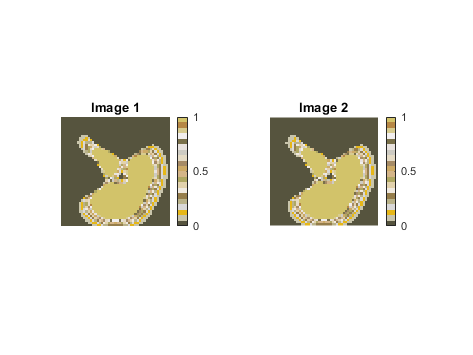


figure;
subplot(1,2,1); imshow(peaks), title('Image 1');
colormap(cmap); colorbar
subplot(1,2,2);  imshow(peaks), title('Image 2');
colormap(cmap); colorbar


% Rescale image
img = imresize(img,[8 NaN])

img = img(:,:,1) =

    0.6504    0.6640    0.7547    0.8643    0.8489    0.8172    0.8505    0.8430    0.9171    0.9316    0.9150    0.8918
    0.8052    0.8261    0.8435    0.9431    0.9192    0.8825    0.8918    0.9548    0.9235    0.9478    0.9308    0.8888
    0.8305    0.8640    0.9245    0.9509    0.9265    0.9086    0.8929    0.9668    0.9235    0.9372    0.9387    0.8981
    0.7947    0.8528    0.9061    0.9043    0.9073    0.8307    0.6956    0.8997    0.9337    0.9293    0.9300    0.8718
    0.7239    0.7973    0.8423    0.8598    0.9271    0.8997    0.8250    0.9266    0.9218    0.9202    0.9253    0.8637
    0.6563    0.7728    0.8726    0.8361    0.9047    0.9044    0.8962    0.9389    0.9290    0.9073    0.9172    0.7620
    0.5971    0.8238    0.7675    0.8074    0.8902    0.8239    0.8089    0.8489    0.8963    0.8262    0.8421    0.7304
    0.6982    0.6268    0.5983    0.8126    0.8108    0.6624    0.5867    0.7150    0.7683    0.7413    0.7904    0.7725


img(:,:,2)

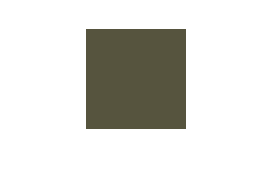


% Show first color in cmap
figure
a = zeros(100,100,3);
a(:,:,1) = cmap(1,1);
a(:,:,2) = cmap(1,2);
a(:,:,3) = cmap(1,3);
imshow(a)


% Convert cmap to LAB
cmap_lab = zeros(5,3);
for i = 1:length(cmap)
    cmap_lab(i,:) = rgb2lab(cmap(i,:));
end

cmap_lab

cmap_lab =    35.3351   -3.2728   13.1943
   79.2085   -3.0117   13.5569
   76.5330    4.0630   75.6262
   86.4155    0.3397    0.1199
   72.2031   -4.1118   21.9077
   53.5633    2.4239   30.5767
   92.9302    0.4780    5.0794
   84.6281   -0.2181   20.3741
   68.0361   -7.5160   36.4548
   75.3419    4.7893   27.0886


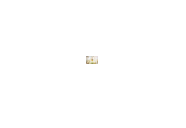


figure
imshow(img);


% generatePaletteLABParts(palette, pearlSize)
pearlSize = 8

pearlSize = 8

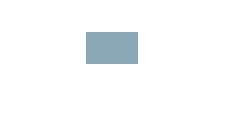

board = createPearlBoard(img, pearlSize, cmap);
imshow(board)

function result = createPearlBoard(image, pearlSize, palette)
    % Input: An image and the size of the pearl (in width)
    % Output: A copy of the image but displayed using pearls
    [x, y, z] = size(image);

    sampleSize = pearlSize;
    pearlSize = pearlSize * 4;

    % Scaling of the resulting image to allow for higher resolution
    board = zeros(x*4,y*4,z,'double');

    mr = mean(mean(image(:,:,1)));
    mg = mean(mean(image(:,:,2)));
    mb = mean(mean(image(:,:,3)));

%     backgroundColor = [std2(image(:,:,1)),std2(image(:,:,2)),std2(image(:,:,3))]
    backgroundColor = [mr,mg,mb];

    board(:,:,1) = backgroundColor(1);
    board(:,:,2) = backgroundColor(2);
    board(:,:,3) = backgroundColor(3);

    for r = 1:sampleSize:x-sampleSize
        for c = 1:sampleSize:y-sampleSize
            part = image(r:r+sampleSize-1,c:c+sampleSize-1, :);
            color = getClosestPaletteColor_e(part, palette);
            
            % Skapa pärlan
            pearl = makePearl(pearlSize, color, backgroundColor);
            board(r:r+pearlSize-1,c:c+pearlSize-1, :) = pearl;
        end
    end

    result = board;
end

function part = makePearl(color, backgroundColor)
    % Input: A part of an image which will be converted to a pearl
    % Output: An image the same size as the part but converted to a pearl

    middle = x/2;
%     color = getMeanColor(part);
%     color = getClosestPaletteColor(part, palette);
    
    for r = 1:x
        for c = 1:y
            d = sqrt((r-middle)^2 + (c-middle)^2);
            if d > uint8(x*0.5)
                part(r,c, :) = backgroundColor;
            elseif d <  uint8(x*0.1)
                part(r,c, :) = backgroundColor;
            else
                part(r,c, :) = color;
            end
        end
    end
end

function color = getMeanColor(part)
    % Input: A part of an image representing a pearl
    % Output: A 1 by 3 vector containing the mean color in the part
    
    redChannel = part(:,:,1);
    greenChannel = part(:,:,2);
    blueChannel = part(:,:,3);
    
    meanR = mean((mean(redChannel)));
    meanG = mean(mean(greenChannel));
    meanB = mean(mean(blueChannel));

    color = [meanR, meanG, meanB];
end

function color = getClosestPaletteColor(part, palette)
    [x, y, ~] = size(part);
    c = zeros(x,y,3, 'double');
    best = 0;
    for i = 1:length(palette)
        c(:,:,1) = palette(i,1);
        c(:,:,2) = palette(i,2);
        c(:,:,3) = palette(i,3);
        d = part - double(c);
        snr = mysnr(part, d);
        if snr > best
            best = snr;
            color = palette(i,:);
        end
    end
end

function color = getClosestPaletteColor_e(part, palette)
    [x, y, ~] = size(part);
    color_part = zeros(x,y,3, 'double');
    best = 999;
    color = [0,0,0];
%     load("project\data\color_lab.mat", "color_lab");
    for i = 1:length(palette)
        color_part(:,:,1) = palette(i,1);
        color_part(:,:,2) = palette(i,2);
        color_part(:,:,3) = palette(i,3);

        part_lab = rgb2lab(part);
        color_part_lab = rgb2lab(color_part);
%         color_part_lab = color_lab(i);

        dE = euclidean_distance_lab_nxnx3(part_lab, color_part_lab);
        delta = mean(mean(dE));

        if delta < best
            best = delta;
            color = palette(i,:);
        end
    end
end

function color_lab = generatePaletteLABParts(palette, size)
    color_part = zeros(size,size,3, 'double');
    for i = 1:length(palette)
        color_part(:,:,1) = palette(i,1);
        color_part(:,:,2) = palette(i,2);
        color_part(:,:,3) = palette(i,3);
        rgb2lab(color_part)
        color_lab(:,:,:,i) = rgb2lab(color_part)
    end
    save("project\data\color_lab.mat", "color_lab")
end